clc; clear; close all;

% Parámetros
n = 10; % Número de nodos (robots)
d = 2;  % Dimensión de x (en R^2)
alpha = 0.001; % Tasa de aprendizaje
max_iter = 100; % Número de iteraciones

% Crear un grafo aleatorio no dirigido (matriz de adyacencia simétrica)
A = randi([0, 1], n, n);
A = triu(A, 1); 
A = A + A'; % Hacerlo simétrico (no dirigido)
A = A - diag(diag(A)); % Asegurar que no haya auto-conexiones

% Normalizar A para que sea doblemente estocástica
A = A ./ sum(A, 2);

%% Inicializar estados x_i en R^2
x = 0.1 + (10 - 0.1)*rand(d, n, max_iter) % Estados de los nodos en cada iteración

x = x(:,:,1) =

    5.8803    5.6056    0.6020    4.6048    4.5292    7.7600    2.6825    8.9656    2.8005    9.1961
    7.6403    4.9581    4.9278    8.8171    6.3364    4.7304    8.9501    9.0084    3.2230    1.3453


x(:,:,2) =

    6.5932    7.2409    4.1403    7.3491    0.2484    8.1864    6.6872    0.7214    7.3191    2.1519
    2.9939    8.3533    1.5965    0.6517    8.7842    5.8614    9.5308    2.2443    2.7140    4.4778


x(:,:,3) =

    7.2646    4.3525    1.8050    8.6722    5.0841    0.3312    7.5271    7.4860    0.9903    9.2324
    2.1842    5.2363    4.8202    7.4860    1.3403    0.7657    7.0733    3.1414    7.1719    4.5767


x(:,:,4) =

    7.6667    8.5515    9.5575    8.7772    6.4308    8.2457    7.4051    0.1655    7.9870    0.1219
    7.3079    0.3810    8.6670    9.9639    0.9086    1.4353    4.2978    4.4142    0.9652    4.5823


x(:,:,5) =

    0.1148    8.2661    0.2714    6.7438    9.4742    3.7144    4.6653    6.2195    5.0569    1.5658
    9.3539    6.338


% Crear matrices M_i y vectores b_i para cada agente
M = zeros(d, d, n); % Matrices M_i
b = zeros(d, n); % Vectores b_i
for i = 1:n
   M(:, :, i) = rand(d, d); % Entradas en [0.1,10]
   b(:, i) = 0.1 + (10 - 0.1) * rand(d, 1); % Entradas en [0.1,10]
end
% Algoritmo de optimización distribuida
for t = 1:max_iter-1
    for i = 1:n
        % Obtener los vecinos del nodo i
        neighbors = find(A(i, :) > 0);
        
        % Calcular el promedio ponderado de los estados de los vecinos
        weighted_sum = zeros(d, 1);
        for j = neighbors
            weighted_sum = weighted_sum + A(i, j) * x(:, j, t);
        end
        
        % Calcular el gradiente de la función de costo local
        grad = 2 * M(:, :, i)' * (M(:, :, i) * x(:, i, t) - b(:, i));
        
        % Actualizar el estado del nodo i
        x(:, i, t+1) = weighted_sum - alpha * grad;
    end
end
% Calcular el valor de consenso (promedio de los estados finales)
consensus_value = mean(x(:, :, end), 2); % Promedio sobre todos los nodos

% Mostrar el valor de consenso
disp('El valor de consenso es:');

El valor de consenso es:


disp(consensus_value);

    5.1423
    5.7447



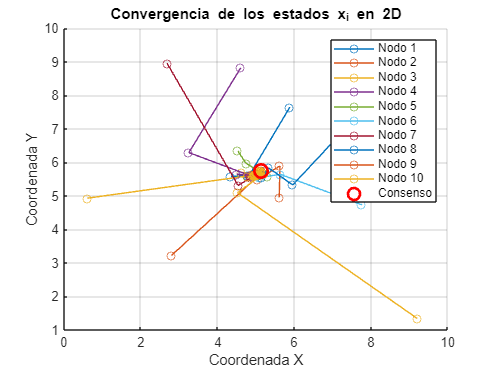


% Graficar la convergencia de los estados en 2D
figure;
hold on;
grid on;
for i = 1:n
    plot(squeeze(x(1, i, :)), squeeze(x(2, i, :)), '-o', 'DisplayName', ['Nodo ' num2str(i)]);
end

% Dibujar el punto de consenso
plot(consensus_value(1), consensus_value(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Consenso');

xlabel('Coordenada X');
ylabel('Coordenada Y');
legend show;
title('Convergencia de los estados x_i en 2D');
hold off;